# Assignment 12

# **Joint assimilation of navigation data coming from different sources**  

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

**1. Generating a true trajectory **$X_i$** of an object motion disturbed by normally distributed random acceleration.**

**2. Generate also true values of range D and Azimuth **$\beta$.

close all;
clear;

m=1;    %Extrapolation steps
N=500;  %Number of points
NE=N-m; %Number of points for the extrapolation error
Mm=500; %Number of runs

%Kalman errors initialization
ErrD=zeros(Mm,N);          %D true estimation error
ErrDE=zeros(Mm,NE);        %D-extrapolated true estimation error
Errbeta=zeros(Mm,N);       %beta true estimation error
ErrbetaE=zeros(Mm,NE);     %beta-extrapolated true estimation error

for M=1:Mm

    X=zeros(1,N);           %X-position
    Y=zeros(1,N);           %Y-position
    X(1)=1000;     %X initial value
    Y(1)=1000;     %Y initial value
    VX=zeros(1,N);          %X-Velocity
    VY=zeros(1,N);          %Y-Velocity
    VX(1)=100;     %X initial velocity
    VY(1)=100;     %Y initial velocity
    T=2;        %Time step
    
    sigma_a=0.3;      %Acceleration noise standard deviation
    
    normaldist=makedist('Normal',0,sigma_a);
    ax=random(normaldist,N,1);            %X-Acceleration noise
    
    normaldist=makedist('Normal',0,sigma_a);
    ay=random(normaldist,N,1);            %Y-Acceleration noise
    
    
    sigma_d_ob1=50;               %Range measurements noise standard deviation
    sigma_beta_ob1=0.004;          %Azimuth measurements noise standard deviation

    D=zeros(1,N);             %Range
    beta=zeros(1,N);          %Azimuth
    D(1)=sqrt(X(1)^2+Y(1)^2); %Range initial value
    beta(1)=atan2(X(1),Y(1));  %Azimuth initial value

    normaldist=makedist('Normal',0,sigma_d_ob1);
    eta_d_ob1=random(normaldist,N,1);            %Range measurements noise vector

    normaldist=makedist('Normal',0,sigma_beta_ob1);
    eta_b_ob1=random(normaldist,N,1);            %Azimuth measurements noise vector
    
    sigma_beta_ob2=0.001;          %Azimuth measurements noise standard deviation

    normaldist=makedist('Normal',0,sigma_beta_ob2);
    eta_b_ob2=random(normaldist,N,1);            %Azimuth measurements noise vector
    
    D_m=D;                                   %Range measurements
    beta_m=beta;                             %Azimuth measurements

    D_m(1)=D(1)+eta_d_ob1(1);                    %Range measurements initialization
    beta_m(1)=beta(1)+eta_b_ob1(1);              %Azimuth measurements initialization

    %Vectors generation
    for i=2:N
        X(i)=X(i-1)+VX(i-1)*T+0.5*ax(i-1)*T^2;        %X vector generation
        VX(i)=VX(i-1)+ax(i-1)*T;                    %X Velocity generation
        Y(i)=Y(i-1)+VY(i-1)*T+0.5*ay(i-1)*T^2;        %Y vector generation
        VY(i)=VY(i-1)+ay(i-1)*T;                    %Y Velocity generation        
        D(i)=sqrt(X(i)^2+Y(i)^2);     %Range vector generation
        beta(i)=atan2(X(i),Y(i));      %Azimuth vector generation

**4. Generate more accurate measurements of azimuth **$\beta^m$ **provided by second observer that arrive between measurement times of the first observer.  **

        
        if rem(i,2)==0
            D_m(i)=NaN;         %Range measurements vector generation
            beta_m(i)=beta(i)+eta_b_ob2(i);   %Azimuth measurements vector generation

**3. Generate measurements of D**$^m, \beta^m$ **of range D and Azimuth **$\beta$** provided by first observer that arrive every 4 seconds.**

        else
            D_m(i)=D(i)+eta_d_ob1(i);         %Range measurements vector generation
            beta_m(i)=beta(i)+eta_b_ob1(i);   %Azimuth measurements vector generation
        end
    end

    Z=[D_m;beta_m];                %Cartesian measurments
    
    x1=D_m(1)*sin(beta_m(1));
    y1=D_m(1)*cos(beta_m(1));
    x3=D_m(3)*sin(beta_m(3));
    y3=D_m(3)*cos(beta_m(3));

**5. Initial conditions for Extended Kalman filter algorithm.**

    %Kalman filter parameters initialization
    Xi=[x3;(x3-x1)/(2*T);y3;(y3-y1)/(2*T)];   %State vector
    P=(10^4)*eye(4);         %P matrix

    %state space matrices
    phi=[1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];

    G=[0.5*T^2 0;T 0;0 0.5*T^2;0 T];
    
    Q=G*G'*sigma_a^2;
    
    xi=Xi(1);
    yi=Xi(3);
    x2y2=xi^2+yi^2;
    h_ob1=[sqrt(xi^2+yi^2);atan2(xi,yi)];
    hprime_ob1=[xi/sqrt(x2y2) 0 yi/sqrt(x2y2) 0; yi/x2y2 0 -xi/x2y2 0];
    
    h_ob2=atan2(xi,yi);
    hprime_ob2=[yi/x2y2 0 -xi/x2y2 0];

    R_ob1=[sigma_d_ob1^2 0;0 sigma_beta_ob1^2];     %Error covariance matrix
    R_ob2=sigma_beta_ob2^2;
    
    %initial kalman gain
    K_ob1=P*hprime_ob1'/(hprime_ob1*P*hprime_ob1'+R_ob1);
    K_ob2=P*hprime_ob2'/(hprime_ob2*P*hprime_ob2'+R_ob2);

    Di=zeros(N,1);       %filtered Range
    betai=zeros(N,1);    %filtered Azimuth

    DiE=zeros(N,1);     %Extrapolated Range
    betaiE=zeros(N,1);  %Extrapolated Azimuth

    Ki=zeros(1,N);      %array of K(1,1)

**6. Develop Kalman filter algorithm to estimate state vector **$X_i$ **(extrapolation and filtration) Start algorithm from time step = 4.** 

**7. Run Kalman filter algorithm over M= 500 runs. Calculate true estimation errors.**

    %Kalman filter
    for i=4:N
        if rem(i,2)~=0
            Xi=phi*Xi;
            P=phi*P*phi'+Q;

            xi=Xi(1);
            yi=Xi(3);
            x2y2=xi^2+yi^2;
            h=[sqrt(xi^2+yi^2);atan2(xi,yi)];
            hprime=[xi/sqrt(x2y2) 0 yi/sqrt(x2y2) 0; yi/x2y2 0 -xi/x2y2 0]; 

            Xi=Xi+K_ob1*(Z(:,i)-h);
            R=R_ob1;
            K_ob1=P*hprime'/(hprime*P*hprime'+R);
            P=(eye(4)-K_ob1*hprime)*P;
        else
            Xi=phi*Xi;
            P=phi*P*phi'+Q;

            xi=Xi(1);
            yi=Xi(3);
            x2y2=xi^2+yi^2;
            h=atan2(xi,yi);
            hprime=[yi/x2y2 0 -xi/x2y2 0]; 

            Xi=Xi+K_ob2*(Z(2,i)-h);
            R=R_ob2;
            K_ob2=P*hprime'/(hprime*P*hprime'+R);
            P=(eye(4)-K_ob2*hprime)*P;
        end
        XiE=Xi;

            for mm=m
                XiE=phi*XiE;     %Extrapolated state vector
            end


            %Range and azimuth estimation (filtered and extrapolated)
            Di(i)=sqrt(Xi(1)^2+Xi(3)^2);
            betai(i)=atan2(Xi(1),Xi(3));
            DiE(i)=sqrt(XiE(1)^2+XiE(3)^2);
            betaiE(i)=atan2(XiE(1),XiE(3));


            %True estimation error calculation
            ErrD(M,i)=(Di(i)-D(i))^2;
            Errbeta(M,i)=(betai(i)-beta(i))^2;

            %Extrapolation error calculation
            if i<N
                ErrDE(M,i)=(DiE(i)-D(i+m))^2;
                ErrbetaE(M,i)=(betaiE(i)-beta(i+m))^2;
            end
    end
end


**8. Compare estimation results with measurement errors of D and **$\beta$**.**

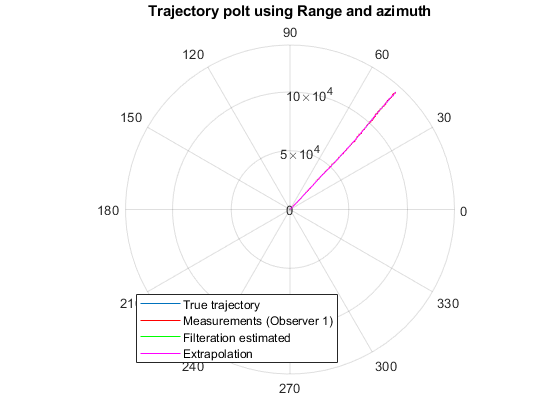

figure
%Trajectory plotting for visualization
polarplot(beta,D)
hold on
I = ~isnan(beta_m) & ~isnan(D_m);
polarplot(beta_m(I),D_m(I),'r')
polarplot(betai,Di,'g')
polarplot(betaiE,DiE,'m')

title('Trajectory polt using Range and azimuth')
legend({'True trajectory','Measurements (Observer 1)','Filteration estimated','Extrapolation'},...
    'location','southwest')

**Comment:**

In this figure above we can see the true trajectory, the measurements, the filtered and the extrapolated states for range and azimuth in polar coordinates. Both the estimation and extrapolation are converging to the true trajectory and very close to it. this gives a good indecation on how effective is our filteration.  

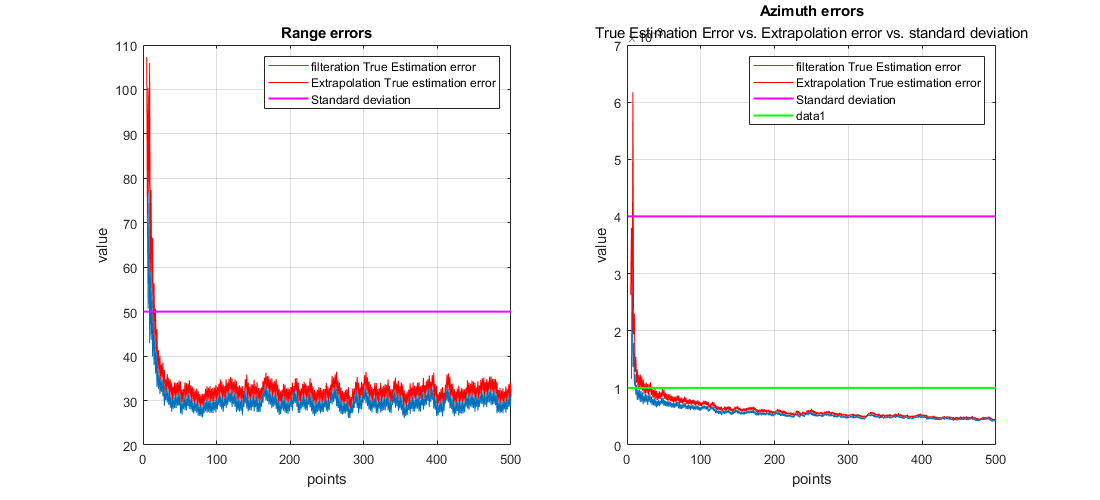

%plotting errors
figure
subplot(1,2,1)
plotErr(ErrD,ErrDE,sigma_d_ob1*ones(1,N),'Range')
subplot(1,2,2)
plotErr(Errbeta,ErrbetaE,sigma_beta_ob1*ones(1,N),'Azimuth')
plot(sigma_beta_ob2*ones(1,N),'g','linewidth',1.5)
set(gcf,'position',[0,0,1100,500]);
subtitle('True Estimation Error vs. Extrapolation error vs. standard deviation')

**Comment:**

In the figure above, the true, calculated and extrapolation errors are ploted for both range and Azimuth are plotted against each other. We can see that, for both variables the filteration and  extrapolation estimation errors are small compared to the standarad deviation of the noise of their prespective measurements. Range Filteration error settles on a value of ~30 while the extrapolation is slightly higher with a value of ~33 compared to the 50 standard deviation for the first observer. Azimuth Filteration error settles on a value of ~0.005 while the extrapolation is slightly higher with a value of ~0.006 compared to the 0.004 and 0.001 standard deviation for the observers.

**9. Analyze again estimation errors of range D and Azimuth **$\beta$. **Please make conclusions why the accuracy of estimation varies for odd and even time steps for both D and **$\beta$.

Comparing the value of standard deviations for Azimuth from observer 1&2 we can see that the final error for the extended Kalman filter was lower than both. Even if the error trend was oscillating in D and $\beta$, which we can relate to the change of accuracy in measurements, but at the end this increased the overall accuarcy of the estimation compared with what we would obtain form the first observer only. The error oscillated in the azimuth filteration having its peeks at the odd points while gradually decreased having its troughs at the even points that depends on the more accurate results form observer two. However, this oscillation was reversed on the range filteration error as the it increased at the even points beacuase actually there is a lack of range measurments in these points.  Moreover this confirms the fact that the more information we have the more accurate results we can get. we will extended on our conclusion here in the learning log.

# Learning Log:  

In this assignment we develop a navigation filter by assimilating data coming from different sources using nonlinear model (Extended Kalman filter). Eventually we summarized what we learnt in the following:

- First of all, we have to priotrize our measurment methods by knowing which is more accurate. In our case, we used one the more accurate one whenever its avaialbe, but maybe in the future wee can use both simultaneously giving different weigts to each one.  

- Also, we can see that although the azimuth filteration error diminishes with time, it is not a smooth curve. Actually, it fluctuates up and down as these peakes represents the odd points while the troughs represents the even points where more accurate measurments are provided and so less error. It became very clear that depending on an extra observer that provides more accurate measurments resulted in much better overall error. 

- Finally, in real applications it is much better not to put all of our trust in a single sensor as it might not work properly at some point, or get affected by some  eviromental factors. But too use multiple sensors(observers) and fusing their observations giving them different weights dependng on how much we trust each one. 

We also tried to verify that by comparing the results while depending only on the first observer applying these consitions to the previous assignment and comparing the results. 

**The figure below show the reults relying on the measurments of the two observers **

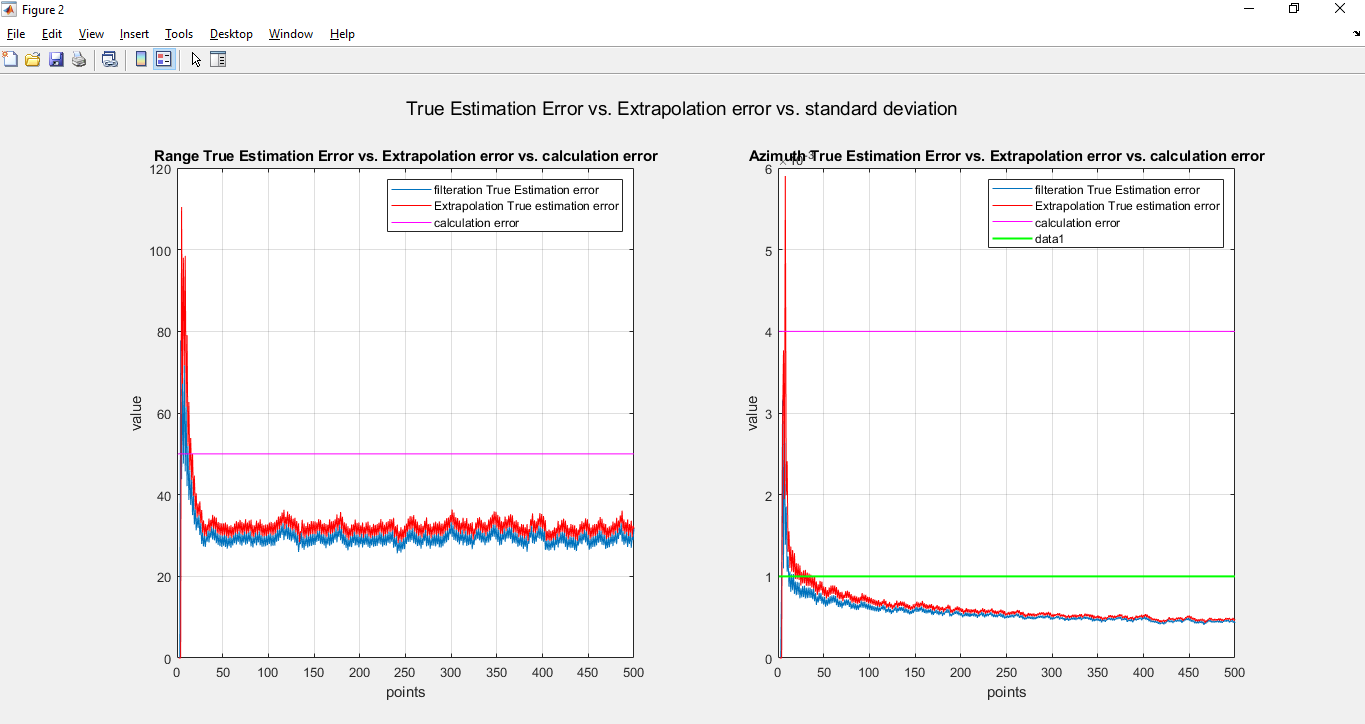

**While below is the results of Assignment 11 **

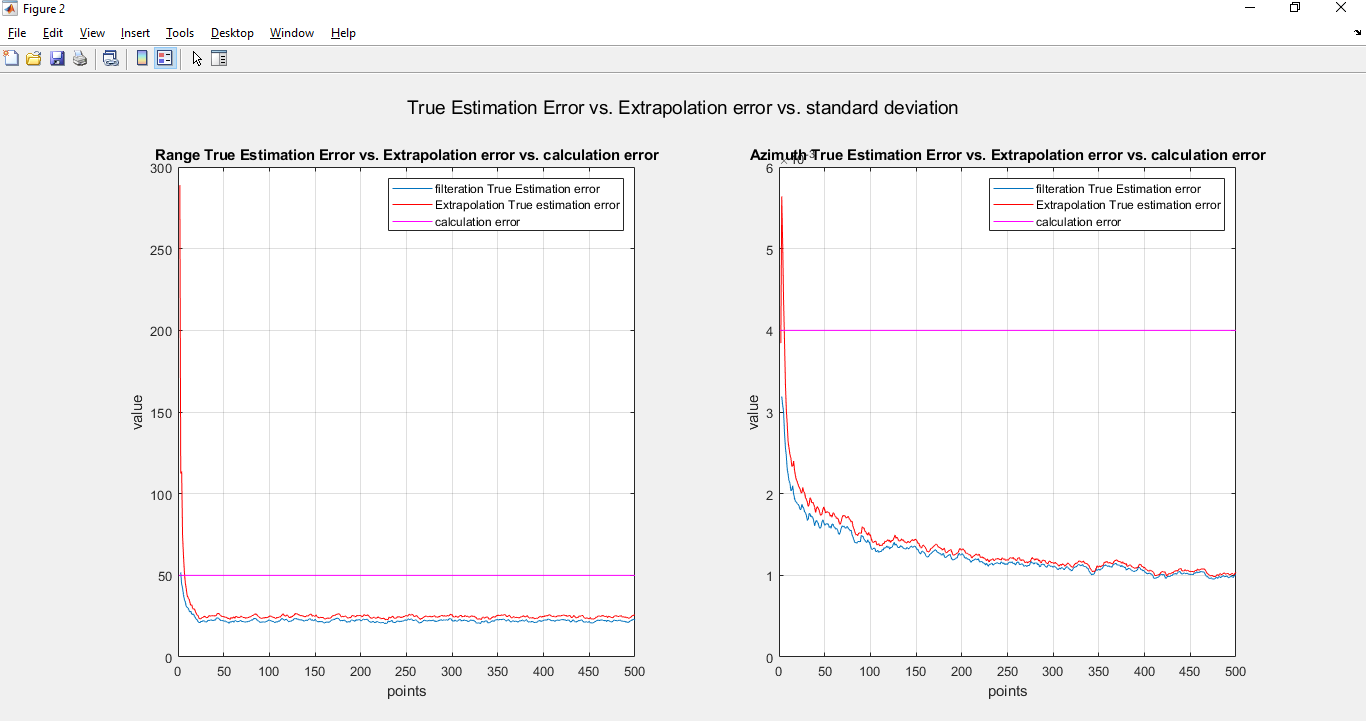

In this two figures above, we can see that the EKF gave better approximation for the Azimuth by using well estimation values from the second observer opposite to what we got in assignment 11 by using the vaues of the same oberver of azimuth.